# Bootstrapping

clear; clc;
cd('/Users/duncan/Documents/GitHub/Advanced-Biomedical-Experimental-Design-and-Statistics/Bootstrapping')

## Population Parameter Estimates

X = [66, 79, 93, 86, 69, 79, 101, 97, 91, 95, 72, 106, 105, 75, 70, 85, 92, 74, 88, 93];
Xm = mean(X) % compute a statistic of interest

Xm = 85.8000

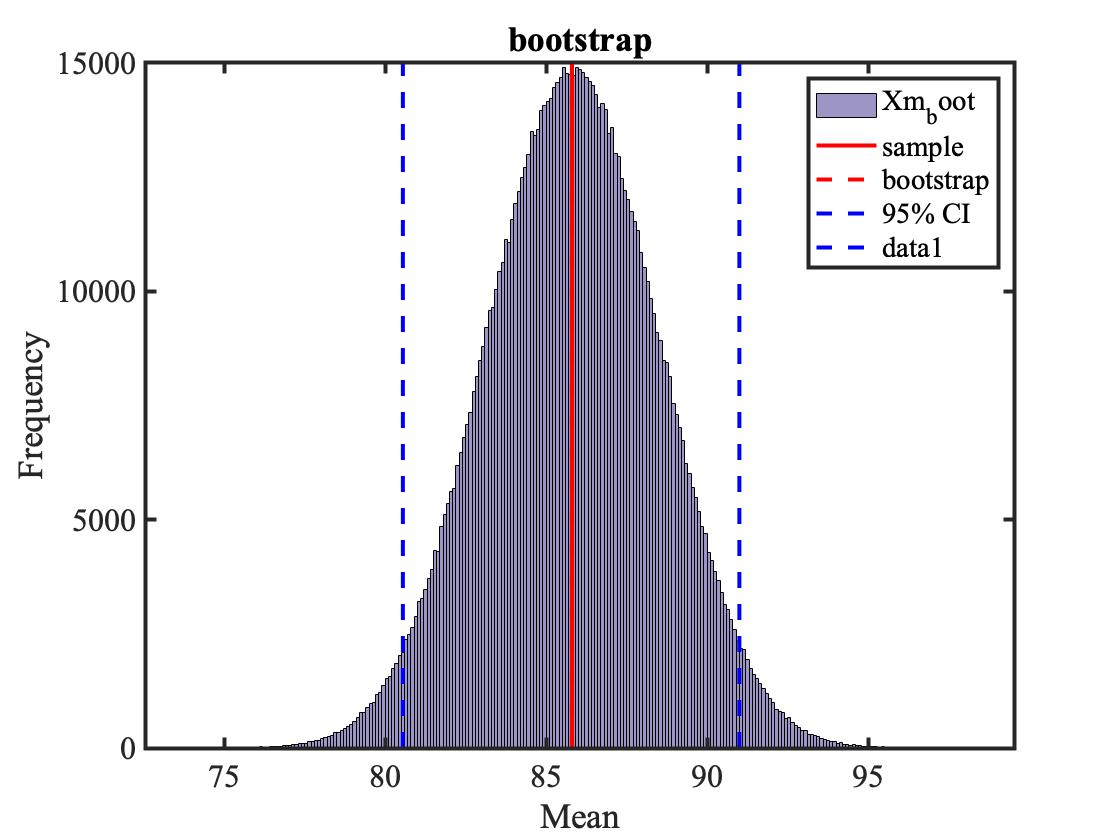


boot_m = 1000000; % how many simulated experiments?
Xm_boot = nan(boot_m,1); % create a list to store our bootstrap values
for i = 1:boot_m
    Xb = datasample(X, length(X), 'replace', true); % generate new sample
    Xm_boot(i) = mean(Xb); % compute statistic of interest
end

figure();
histogram(Xm_boot);
hold on 
plot([mean(Xm) mean(Xm)], get(gca, 'ylim'), 'r', 'displayname', 'sample')
plot([mean(Xm_boot) mean(Xm_boot)], get(gca, 'ylim'), 'r--', 'displayname', 'bootstrap')
ci95 = prctile(Xm_boot, [2.5, 97.5]); 
plot([ci95(1) ci95(1)], get(gca, 'ylim'), 'b--', 'displayname', '95% CI');
plot([ci95(2) ci95(2)], get(gca, 'ylim'), 'b--');
xlabel('Mean')
ylabel('Frequency')
legend()
title('bootstrap')

## Hypothesis Testing - Two Sample

g_control = [87,90,82,77,71,81,77,79,84,86,78,84,86,69,81,75,70,76,75,93];
g_drug = [74,67,81,61,64,75,81,81,81,67,72,78,83,85,56,78,77,80,79,74];
% our statistic of interest here is the difference between means
abs_stat_obs = abs(mean(g_control) - mean(g_drug)) % good practice to take absolute value as to not mess up logical indexing 

abs_stat_obs = 5.3500

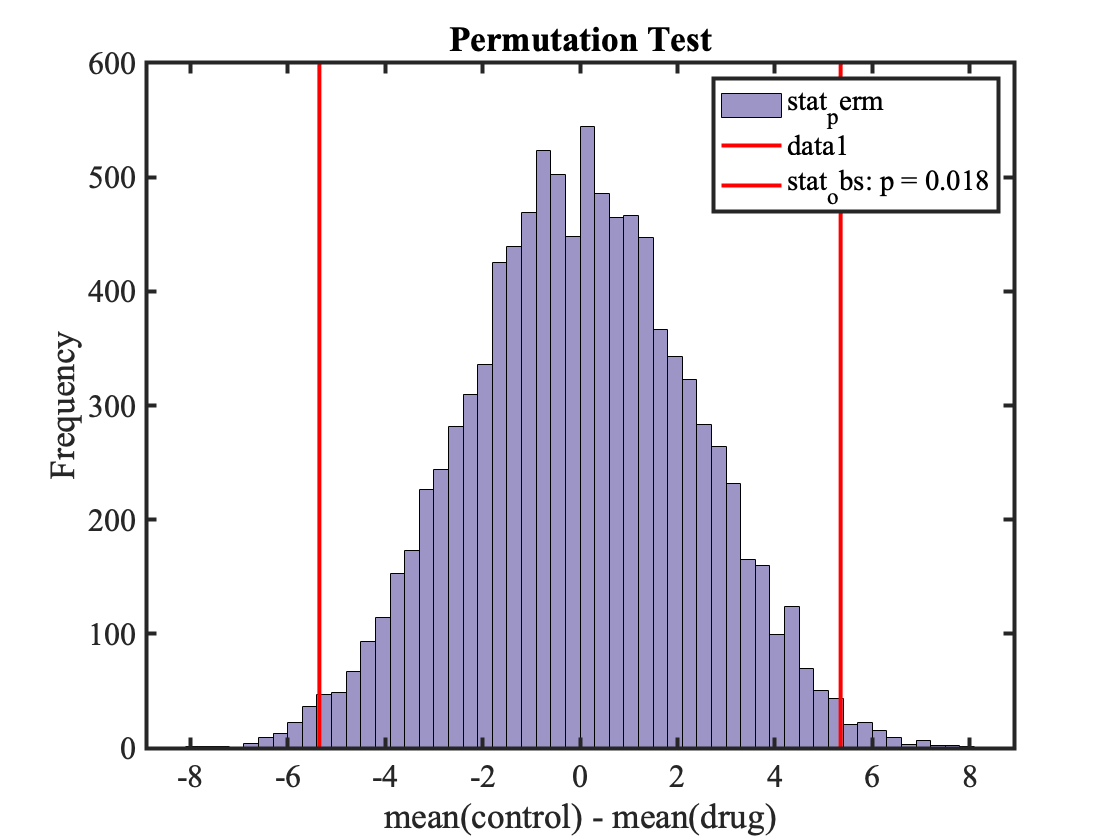

n_perm = 10000; % how many simulated experiments?
stat_perm = nan(n_perm,1); % create a list to store our permutation test values
g_control_n = length(g_control);
g_drug_n = length(g_drug);
g_bucket = [g_control, g_drug];
g_bucket_n = length(g_bucket);
for i = 1:n_perm
    % reconstitute both groups, ignoring original labels
    permuted_bucket = datasample(g_bucket, g_bucket_n, 'replace', false);
    perm_control = permuted_bucket(1:g_control_n);
    perm_drug = permuted_bucket(g_control_n:(g_control_n+g_drug_n));
    stat_perm(i) = mean(perm_control) - mean(perm_drug);
end

pval = (sum(stat_perm <= -abs_stat_obs) + sum(stat_perm >= abs_stat_obs)) / n_perm; % logical indexing 

figure();
histogram(stat_perm);
hold on 
plot([abs_stat_obs abs_stat_obs], get(gca, 'ylim'), 'r-');
plot([-abs_stat_obs -abs_stat_obs], get(gca, 'ylim'), 'r-', 'displayname', sprintf('stat_obs: p = %.3f', pval));
xlabel('mean(control) - mean(drug)');
ylabel('Frequency');
legend()
title('Permutation Test')

## Power Calculations

g_control = [87,90,82,87,71,81,77,79,84,86,78,84,86,69,81,75,70,76,75,93];
g_drug = [74,73,81,65,64,72,76,81,81,67,72,78,83,75,66,78,77,80,79,74];
p_obs = ranksum(g_control, g_drug); 
n_boot = 10000;
p_boot = nan(n_boot,1); 
for i = 1:n_boot
    b_control = datasample(g_control,length(g_control),'replace', true);
    b_drug = datasample(g_drug,length(g_drug),'replace', true);
    p_boot(i) = ranksum(b_control, b_drug);
end

power = sum(p_boot <= .05) / n_boot

power = 0.7682

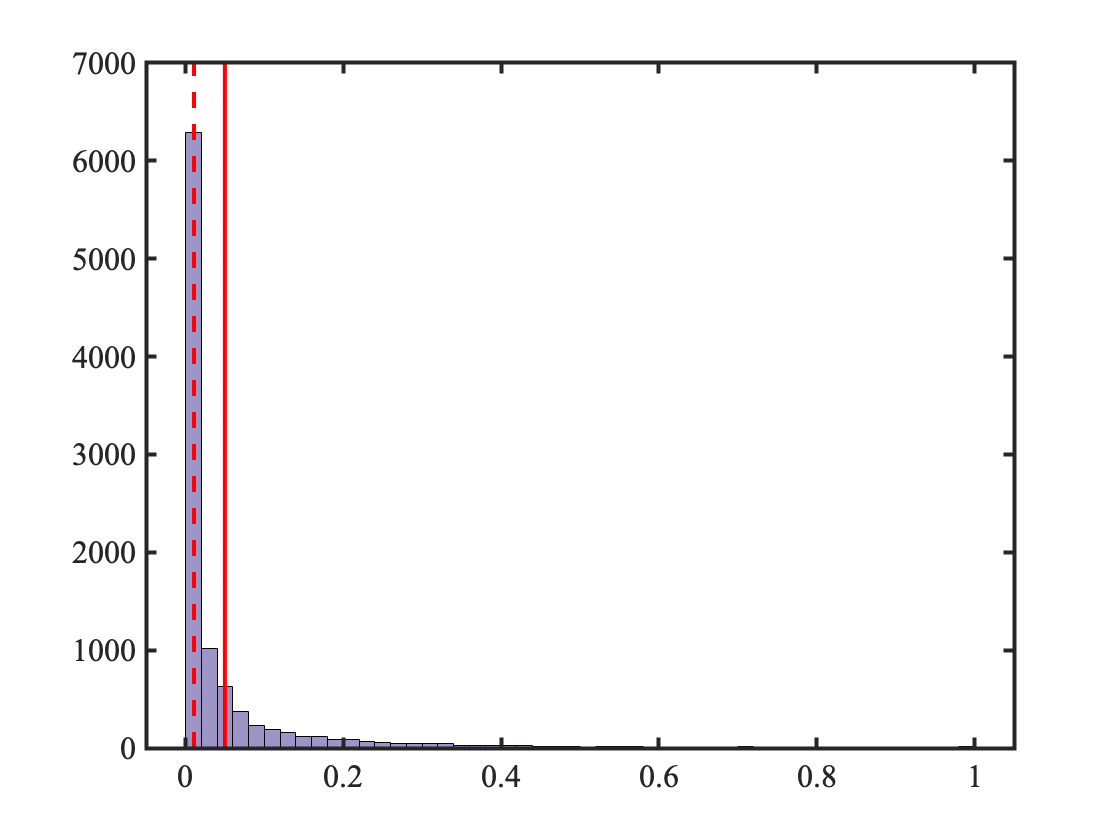


figure();
histogram(p_boot);
hold on 
plot([0.05 0.05], get(gca, 'ylim'), 'r-');
plot([p_obs p_obs], get(gca, 'ylim'), 'r--')

## Model Fitting - Data

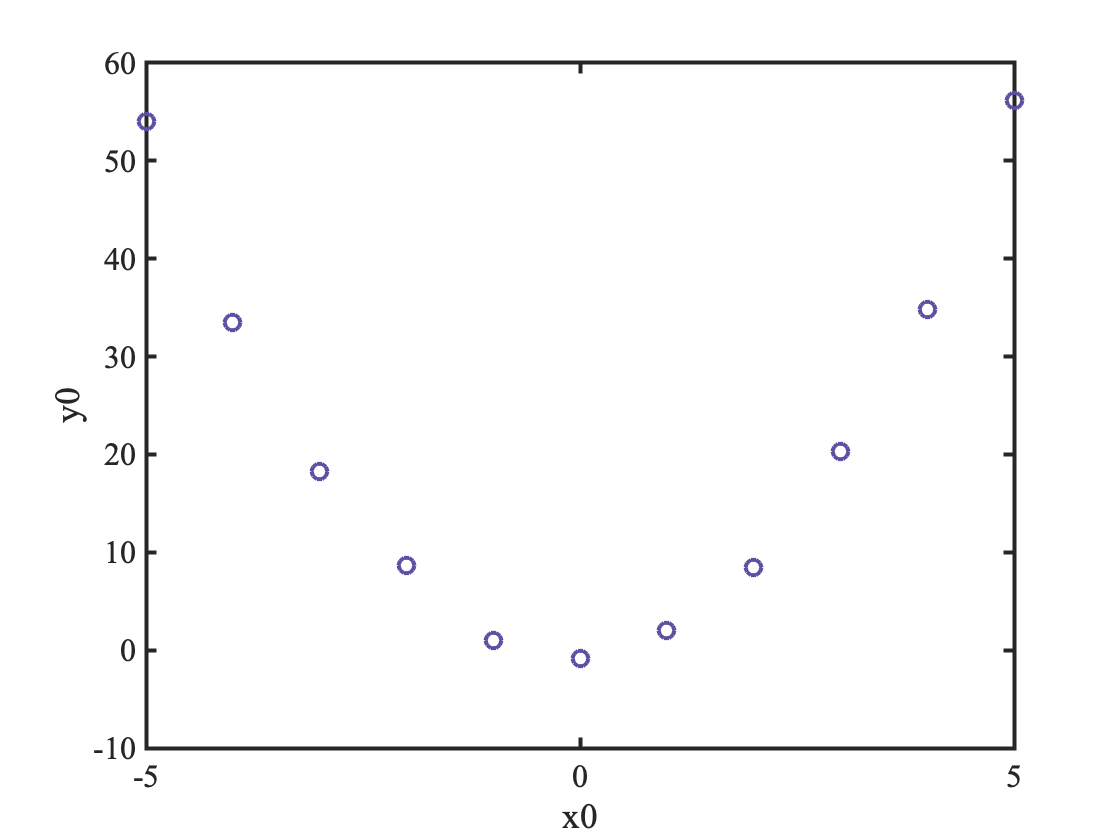

x0 = -5:5; 
% Can use commented out code to generate data
% noise = normrnd(0,1, [11 1]);
% c = 2.2; % pretend you don't know what the constant is (we are going to estimate this)
% y0 = c * x0^2 + noise;
% y0
y0 = [54.000534, 33.485031, 18.217317, 8.599760, 1.018073, -0.903174, 2.019343, 8.475278, 20.347628, 34.768279, 56.204352]; 

figure()
plot(x0, y0, 'o', 'markersize', 8)
xlabel('x0')
ylabel('y0')

## Model Fitting - Loss Function

lse = @(c,x,y) sum((y - (c*x.^2)).^2);

c_init = 5;
params_LSE = fminsearch(@(x) lse(x, x0, y0), c_init)

params_LSE = 2.1785

## Model Fitting - Bootstrapping

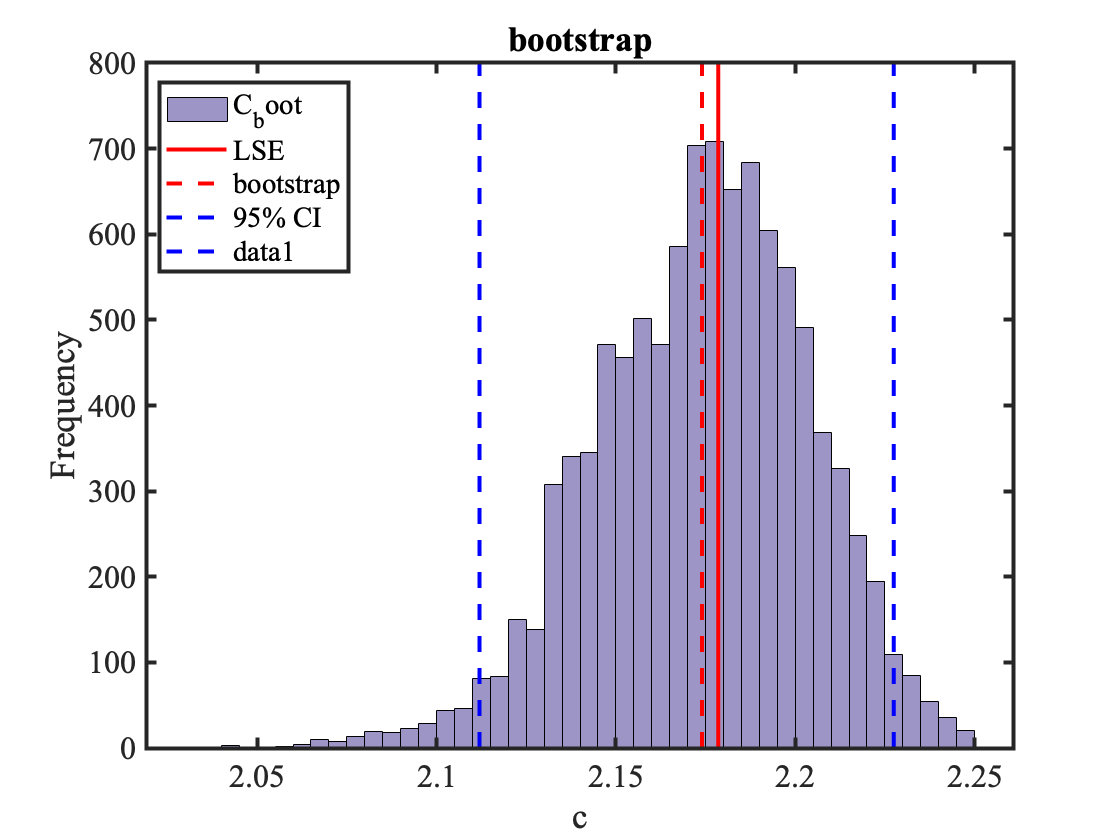

boot_m = 10000; % how many simulated experiments?
C_boot = nan(boot_m,1); % create a list to store our bootstrap values
X = nan(size(x0)); 
Y = nan(size(y0)); 
for i = 1:n_boot
    for j = 1:length(x0) % inner loop used to preserve x,y pairs
        k = datasample(1:length(x0), 1);  % sample random integer
        X(j) = x0(k); % use integer to sample x,y pair
        Y(j) = y0(k);
    end
    C_boot(i) = fminsearch(@(x) lse(x, X, Y), c_init); 
end

figure();
histogram(C_boot);
hold on 
plot([params_LSE params_LSE], get(gca, 'ylim'), 'r-', 'displayname', 'LSE');
plot([mean(C_boot) mean(C_boot)], get(gca, 'ylim'), 'r--', 'displayname', 'bootstrap');
ci95 = prctile(C_boot, [2.5 97.5]); 
plot([ci95(1) ci95(1)], get(gca, 'ylim'), 'b--', 'displayname', '95% CI');
plot([ci95(2) ci95(2)], get(gca, 'ylim'), 'b--');
xlabel('c');
ylabel('Frequency');
legend('location', 'best');
title('bootstrap');

## Plotting Model Fits

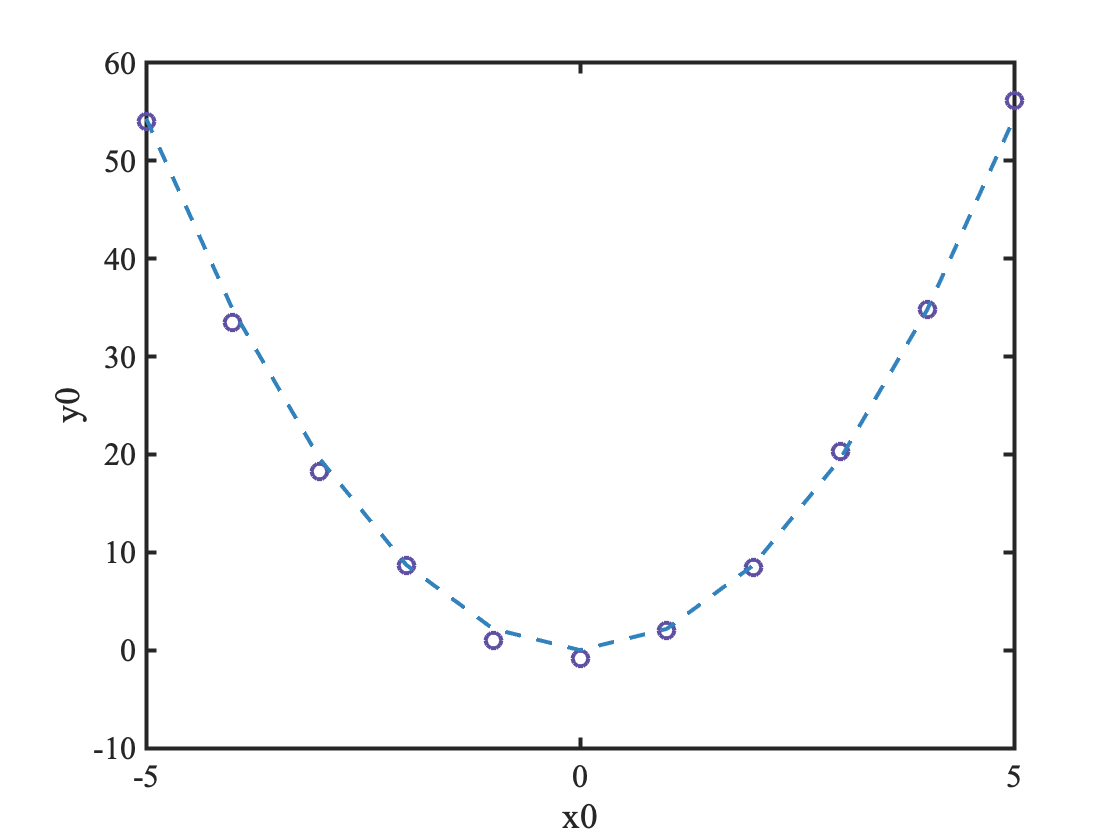

yfit = mean(C_boot)*x0.^2;

figure();
plot(x0, y0, 'o', 'markersize', 8); 
hold on 
plot(x0, yfit, '--')
xlabel('x0')
ylabel('y0')